### Parameters for analysis

clear

Parameters for SP2 data:

data_path  = fullfile( 'X:','Groups','SPA','01_Data_Raw_Summary_Processed', ...
                      'EEG','Participant_Data','03_Processed_Data' );
sp2_path   = fullfile(data_path,'01_Subject_Info_For_Processing','SP2_Processed_2022-10-03');
sp2_fields = {                              ...
                'scq_total',                ...
                'Tactile Modality',         ...
                'Tactile Hyper-reactivity', ...
                'Tactile Hypo-reactivity',  ...
                'Auditory Modality',        ...
                'Auditory Hyper-reactivity',...
                'Auditory Hypo-reactivity', ...
                'Visual Hyper-reactivity',  ...
                'Visual Hypo-reactivity',   ...
                'Oral Hyper-reactivity',    ...
                'Oral Hypo-reactivity',     ...
                'Movement Modality',        ...
                'Social Emotional Modality',...
                'Attentional Modality',     ...
                'Seeking Domain',           ...
                'Avoiding Domain',          ...
                'Sensitivity Domain',       ...
                'Registration Domain'      ...
           };

Parameters for spectral events data:

task      = '02_Baseline';
band      = 'beta';
method    = 1;
chans     = [36 104]; % list of chans to plot
averaging = 'spec_events'; % averaging method
time_win  = [0 5000]; % time window to use relative to stim onset (ms)
beapp_tag = '_wbadchan_5sec';

Group assignment information:

group_name     = {'TD','ASD','SPD'};
groups_to_plot = 1:2;
grp_table      = fullfile(data_path,'01_Subject_Info_For_Processing','Group_Assignments.mat');

Parameters for plotting:

conds_to_inc = 0; % if a subset, 0 to include all
evt_per_sec  = abs(sum(time_win))/1000;
rm_outliers  = false;
plot_var     = false;
save_fig     = false;
% equal_Ns     = false;
% by_cond      = false;
% fields to extract from spec_events structs
features{1,:} = {'eventnumber','maximapowerFOM','duration','Fspan'};
if evt_per_sec > 0
    features{2,:} = {'Event rate (Hz)','Power (FOM)','Duration (ms)','F-span (Hz)'};
else
    features{2,:} = {'Events per segment','Power (FOM)','Duration (ms)','F-span (Hz)'};
end

 

%% get information for plotting
colors   = {'#4444c9','#32a852','#db4214'};
time_str = get_time_win_str(time_win);
chan_str = get_chan_str({},chans);
if isempty(chan_str)
    chan_str = '1020';
end
task_abbrevs = containers.Map({'02_Baseline','stepwise_loudness',  ...
                               'auditory_temporal_habituation', ...
                               'tactile_spatial_suppression',   ...
                               'tactile_temporal_habituation'}, ...
                               {'Resting','SL','ATH','TSS','TTH'});
task_abb = task_abbrevs(task);

%% load group assignment table 
load(grp_table,'groups')

%% load sp2 table
sp2_table = readtable(sp2_path,'PreserveVariableNames',true);
sp2_table = rmmissing(sp2_table);
sp2_table.id = string(sp2_table.study_id);
sp2_table.Properties.RowNames = sp2_table.id;

%% load spectral events data
n_feats = length(features{1});
n_chans = length(chans);
% load based on averaging method
switch averaging
    %% average eeg channels first, then run spectral events
    case 'eeg'
    load_chans = strrep(int2str(chans),' ','');
    if isempty(chans)
        load_chans = '1020';
    end
    % load channel SET data
    tag = [band '_' int2str(method) '_' load_chans beapp_tag];
    load(fullfile(data_path,task,'spec_events',[tag '.mat']),'spec_events');
    % sort data by group
    sorted_eeg = sort_data_by_group_old(spec_events,groups,group_name);
    clear spec_events
    
    %% run spectral events on each channel, then average outputs
    case 'spec_events'
    if isempty(chans)
        chans = [22 9 33 24 124 122 36 104 58 62 96 70 83 45 108 52 92 11];
    end
    n_chans = length(chans);
    for i_c = 1:n_chans
        % load channel SET data
        tag = [band '_' int2str(method) '_' int2str(chans(i_c)) beapp_tag];
        load(fullfile(data_path,task,'spec_events',[tag '.mat']),'spec_events');
        % sort data by group
        sorted_eeg(i_c) = sort_data_by_group_old(spec_events,groups,group_name);
        clear spec_events
    end
end

% get subject means and standard deviations
[data_mean,data_std] = subj_avg_spec_events(sorted_eeg,features{1},conds_to_inc);
%% TODO: AVERAGE MULTIPLE CHANS

### Results

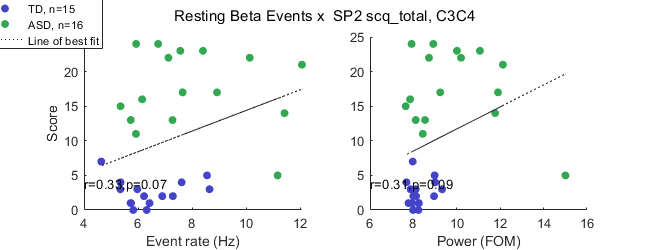

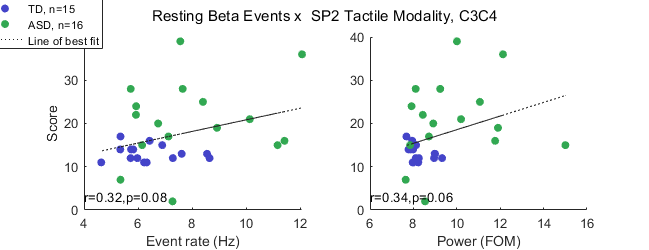

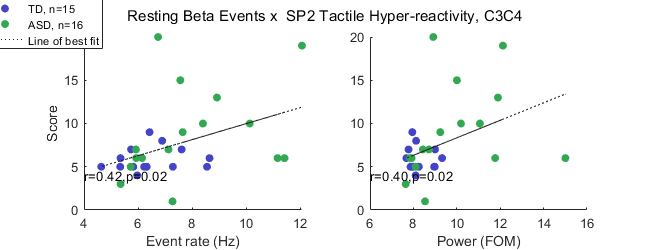

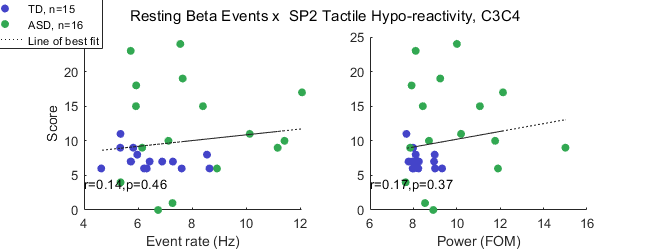

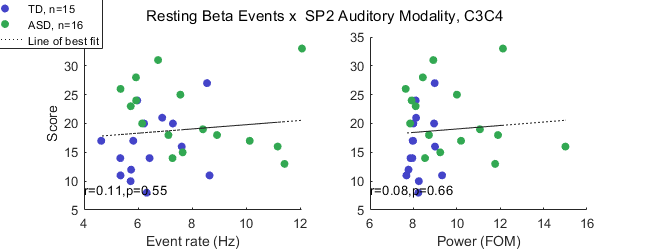

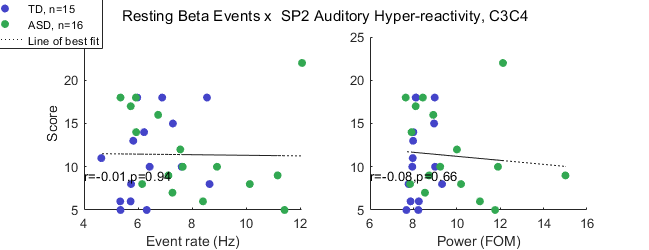

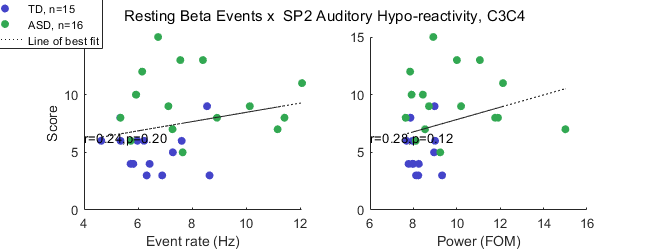

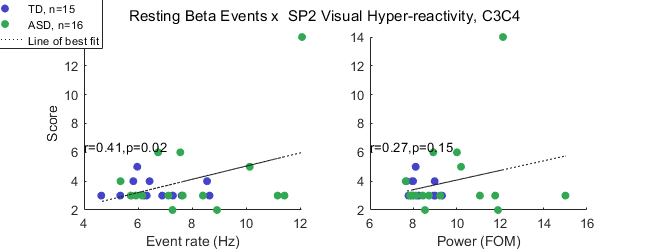

% iterate through sp2 fields
for i_m = 1:length(sp2_fields) 
    sp2_field  = sp2_fields{i_m};
    plot_title = [task_abb ' ' capitalize(band) ' Events x  SP2 ' sp2_field ', C3C4'];% chan_str];

    % iterate through features
    f = figure('Position',[0 0 650 250]);
    sgtitle(plaintext(plot_title))
    for i_f = 1:2%n_feats
        subplot(1,2,i_f), hold on
        feat = features{1}{i_f};
        % iterate through groups
        eeg = cell(1,length(groups_to_plot)); sp2 = eeg;
        for i_g = groups_to_plot
            group = group_name{i_g};
            % create table from group average measure
            if plot_var
                group_eeg = struct2table(data_std.(group));
            else
                group_eeg = struct2table(data_mean.(group));
            end
            group_eeg.Properties.RowNames = group_eeg.id;
            % get ids to plot
            ids = intersect(sp2_table.id,group_eeg.id);
            n_subj = int2str(length(ids));
            group_label = [group ', n=' n_subj];
            
            % plot group eeg x sp2 measure
            eeg{i_g} = group_eeg.(feat)(ids); sp2{i_g} = sp2_table.(sp2_field)(ids);
            scatter( eeg{i_g}, sp2{i_g}, 'filled', 'MarkerFaceColor', colors{i_g}, ...
                    'DisplayName', group_label )
        end
        eeg = cell2mat(eeg'); sp2 = cell2mat(sp2');
        
        % remove outliers, if selected
        if rm_outliers
            outliers = logical((abs(zscore(eeg))>3) + (abs(zscore(sp2))>3));
            eeg(outliers) = []; sp2(outliers) = [];
        end

        % get line of best fit
        pf = polyfit(eeg,sp2,1);
        y_fit = polyval(pf,eeg);
        plot(eeg,y_fit,':','Color','#222','DisplayName','Line of best fit')

        % correlate measures
        [r,pf] = corrcoef(eeg,sp2);
        str=sprintf('r=%1.2f,p=%1.2f',r(1,2),pf(1,2));
        T = text(min(get(gca, 'xlim')), min(get(gca, 'ylim'))+5, str); 
        set(T,'fontsize',10,'verticalalignment','top','horizontalalignment','left');

        % style plot
        xlabel(features{2}{i_f}) %,'FontSize',5)
        if i_f == 1, ylabel('Score'); end
    end
    % shrink legend and move off of plots
    [h,~] = legend('show');
    set(h,'position',[0.05 0.87 0.03 0.07]);

    % save figure
    if save_fig
        pause(0.2)
        fig_path = fullfile(data_path,task,'figures','spec_events');
        if ~exist(fig_path,'dir'), mkdir(fig_path); end
        if plot_var
            fig_fname = [band '_groups_' chan_str '_std_' sp2_field];
        else
            fig_fname = [band '_groups_' chan_str '_mean_' sp2_field];
        end
        fig_fname = fullfile(fig_path,fig_fname);
        saveas(f,fig_fname,'jpg')
    end
end